# Numerical simulator of fluid flow in porous media in 2D for one phase using FDM

The main idea is to create a simple numerical reservoir simulator that solves the diffusivity equation for fluid flow in porous media in 2D. For this version, we are going to do the following steps:

- Define the equation to solve.

- Introduce the data (k, porosity, ct, viscosity, density of the water, height of the cells, number of blocks, length of each block (in x and y), total time to run the simulation and time steps duration).

- Use the Von Neumann stability analysis to obtain the maximum time step for an explicit scheme.

- If the Von Neumann stability analysis show us that the explicit scheme is unstable, the scheme used is going to be  Crank - Nicolson.

- Define the IC (Initial pressure for all the cells) and BC (Pressure for 2 cells or rate production/injection in 2 cells).

- Present the discretized equation using the explicit scheme and the Crank Nicolson scheme.

- Initialize the matrices and assign the initial values.

- Calculate all the values of the blocks for each successive time step using the scheme selected.

- Graph the values of pressure vs. time.

Future versions may include:

- Multiphase

- Not constant properties (petrophysics and fluids).

- Option to add more wells

- 3D grid

Leonardo Arana Parodi

leonardo.arana.parodi@gmail.com

August, 2025

Equation to solve:


$$\frac{\partial^2 }{\partial x^2 }p+\frac{\partial^2 }{\partial y^2 }p=\frac{\phi \mu C_t }{k}\frac{\partial }{\partial t}p+\frac{q_m \mu }{k\rho }$$


Equation obtained from the book "Petroleum Reservoir Simulation" Aziz and Settari. Eq. 2.43.

Assumptions:

Constant values: porosity, viscosity, Ct, permeability and density.

Injection: $q_m$<0

Production: $q_m$>0

Units of $q_m$: $\frac{\textrm{kg}}{m^3 s}$

# 1. Input data

clc; clear; close all;

## 1.1. Petrophysical and fluids data input

%Data:
k=50*9.869233E-16; %[m^2];
mu=0.001; %[Pa*s];
ct=4.5E-10; %[1/Pa];
poro=0.2; %[dim.];
dens=1000; %[kg/m^3];
nblocks=10; %[nblocks in x and nblocks in y]...total model of nblocks by nblocks
deltax=1; %[m] length of each block;
height= 1; %[m];
nsteps=50; %;
tstep=5; %[s] duration of each time step;

## 1.2. Initial Conditions

pinit=100E5; %[Pa]; IC for all the cells

## 1.3. Boundary conditions

### 1.3.1. Define the type of Boundary conditions

%Define type of BC: 0=pressure, 1=rate;
bctype=0;

### 1.3.2. Boundary conditions of Injection

pbcinj= 200E5; %[Pa]; BC of injection for 1 cell
qbcinj=-20/(24*60*60); %[m^3/s];
cbcinjx=4; %coordinate x of injection;
cbcinjy=7; %coordinate y of injection;

### 1.3.3. Boundary conditions of production

pbcprd= 5E5; %[Pa]; BC of production for 1 cell
qbcprd=15/(24*60*60); %[m^3/s];
cbcprdx=10; %coordinate x of production;
cbcprdy=10; %coordinate y of production;

vcell=deltax^2*height; %[m^3] don't touch this;

# 2. Von Neumann Stability analysis

Doing $\Delta x=\Delta y$ and calling it $\Delta h$

Equation used:


$$\textrm{Max}\;\textrm{Time}\;\textrm{step}\;\textrm{stable}=\frac{{\Delta h}^2 \phi \mu c_t }{2k}$$


Taken from the course "Numerical Methods for Engineers" of Jeffrey Chasnov (HKUST).

tstepstab=deltax^2*poro*mu*ct/(2*k);
fprintf("The maximum possible deltat is: " + tstepstab +" seconds")

The maximum possible deltat is: 0.91192 seconds

if tstepstab>tstep
    implicit=0;
    fprintf("The scheme to use is going to be the Explicit Scheme. Increase the time step or reduce the deltax if you want to use the Crank Nicolson scheme.");
else
    implicit=1;
    fprintf("The scheme to use is going to be the Crank Nicolson Scheme. Reduce the time step or increase the deltax if you want to use the explicit scheme.");
end

The scheme to use is going to be the Crank Nicolson Scheme. Reduce the time step or increase the deltax if you want to use the explicit scheme.

# 3. Equations used for the discretization

Doing:


$$\alpha =\frac{k\Delta t}{\phi \mu c_t {\Delta h}^2 }$$


## 3.1. Explicit scheme

Discretized equation using the explicit scheme:


$${p_{i,j} }^{t+1} ={p_{i,j} }^t +\alpha *\left\lbrack {p_{i+1,j} }^t +{p_{i-1,j} }^t -4{p_{i,j} }^t +{p_{i,j+1} }^t +{p_{i,j-1} }^t \right\rbrack -\frac{q_m \Delta t}{\phi c_t \rho }$$


## 3.2. Crank Nicolson scheme


$$\left(1+2\alpha \right){p_{i,j} }^{t+1} -\frac{\alpha }{2}\left\lbrack {p_{i+1,j} }^{t+1} +{p_{i-1,j} }^{t+1} +{p_{i,j+1} }^{t+1} +{p_{i,j-1} }^{t+1} \right\rbrack =\left(1-2\alpha \right){p_{i,j} }^t +\frac{\alpha }{2}\left\lbrack {p_{i+1,j} }^t +{p_{i-1,j} }^t +{p_{i,j+1} }^t +{p_{i,j-1} }^t \right\rbrack -\frac{q_m \Delta t}{\phi c_t \rho }$$


Here the problem is proposed as operations of matrices:


$$\mathrm{Ax}p^{t+1} =\mathrm{Bx}p^t -\mathrm{source}$$


# 4. Generate the matrix of pressures and sources

p=zeros(nblocks, nblocks, nsteps);
p(:,:,1)=ones(nblocks,nblocks)*pinit; %Assign the initial pressure value to the matrix of the first time step.

Define a matrix with the sources.

s=zeros(nblocks, nblocks);
if bctype==1
    s(cbcinjx, cbcinjy)=qbcinj*tstep/(poro*vcell*ct);
    s(cbcprdx, cbcprdy)=qbcprd*tstep/(poro*vcell*ct);
end

Generate the "alpha" variable


$$\alpha =\frac{k\Delta t}{\phi \mu c_t {\Delta h}^2 }$$


alpha=k*tstep/(poro*mu*ct*deltax^2);

# 5. Explicit scheme

Assign the values for each block of all the other time steps (from the 2nd to the end)


$${p_{i,j} }^{t+1} ={p_{i,j} }^t +\alpha *\left\lbrack {p_{i+1,j} }^t +{p_{i-1,j} }^t -4{p_{i,j} }^t +{p_{i,j+1} }^t +{p_{i,j-1} }^t \right\rbrack -\frac{q_m \Delta t}{\phi c_t \rho }$$



if implicit==0
    for t=2:nsteps
        for i=2:(nblocks-1)
            for j=2:(nblocks-1)
                p(i,j,t)=p(i,j,t-1)+alpha*[p(i+1,j,t-1)+p(i-1,j,t-1)-4*p(i,j,t-1)+p(i,j+1,t-1)+p(i,j-1,t-1)];
            end
        end
        %Fill the first column
        for i=2:(nblocks-1)
            p(i,1,t)=p(i,1,t-1)+alpha*[p(i+1,1,t-1)+p(i-1,1,t-1)-4*p(i,1,t-1)+p(i,2,t-1)+p(i,1,t-1)];
        end

        %Fill the last column
        for i=2:(nblocks-1)
            p(i,nblocks,t)=p(i,nblocks,t-1)+alpha*[p(i+1,nblocks,t-1)+p(i-1,nblocks,t-1)-4*p(i,nblocks,t-1)+p(i,nblocks,t-1)+p(i,nblocks-1,t-1)];
        end
    
        %Fill the first row
        for j=2:(nblocks-1)
            p(1,j,t)=p(1,j,t-1)+alpha*[p(2,j,t-1)+p(1,j,t-1)-4*p(1,j,t-1)+p(1,j+1,t-1)+p(1,j-1,t-1)];
        end

        %Fill the last row
        for j=2:(nblocks-1)
            p(nblocks,j,t)=p(nblocks,j,t-1)+alpha*[p(nblocks,j,t-1)+p(nblocks-1,j,t-1)-4*p(nblocks,j,t-1)+p(nblocks,j+1,t-1)+p(nblocks,j-1,t-1)];
        end
        %Fill the (1,1) corner
        p(1,1,t)=p(1,1,t-1)+alpha*[p(2,1,t-1)+p(1,1,t-1)-4*p(1,1,t-1)+p(1,2,t-1)+p(1,1,t-1)];
        %Fill the (1,nblocks) corner
        p(1,nblocks,t)=p(1,nblocks,t-1)+alpha*[p(1,nblocks,t-1)+p(1,nblocks,t-1)-4*p(1,nblocks,t-1)+p(1,nblocks,t-1)+p(1,nblocks-1,t-1)];
        %Fill the (nblocks,1) corner
        p(nblocks,1,t)=p(nblocks,1,t-1)+alpha*[p(nblocks,1,t-1)+p(nblocks-1,1,t-1)-4*p(nblocks,1,t-1)+p(nblocks,2,t-1)+p(nblocks,1,t-1)];
        %Fill the (nblocks, nblocks) corner
        p(nblocks,nblocks,t)=p(nblocks,nblocks,t-1)+alpha*[p(nblocks,nblocks,t-1)+p(nblocks-1,nblocks,t-1)-4*p(nblocks,nblocks,t-1)+p(nblocks,nblocks,t-1)+p(nblocks,nblocks-1,t-1)];
    
        %Adding the BC defined:
        if bctype==0
            fixed_cells = [cbcprdx cbcprdy; cbcinjx cbcinjy];    
            fixed_values = [pbcprd; pbcinj];        
            fixed_idx = (fixed_cells(:,1)-1)*nblocks + fixed_cells(:,2); 
            p_next=p(:,:,t);
            p_vec = p_next(:);
            p_vec(fixed_idx) = fixed_values;
            p_next = reshape(p_vec, nblocks, nblocks);
            p(:,:,t)=p_next;
        else

            p(:,:,t)=p(:,:,t)-s; %Adding the source:
        end
    end
end


# 6. Crank Nicolson scheme


$$\left(1+2\alpha \right){p_{i,j} }^{t+1} -\frac{\alpha }{2}\left\lbrack {p_{i+1,j} }^{t+1} +{p_{i-1,j} }^{t+1} +{p_{i,j+1} }^{t+1} +{p_{i,j-1} }^{t+1} \right\rbrack =\left(1-2\alpha \right){p_{i,j} }^t +\frac{\alpha }{2}\left\lbrack {p_{i+1,j} }^t +{p_{i-1,j} }^t +{p_{i,j+1} }^t +{p_{i,j-1} }^t \right\rbrack -\frac{q_m \Delta t}{\phi c_t \rho }$$


Here the problem is proposed as operations of matrices:


$$\textrm{Ax}p^{t+1} =\textrm{Bx}p^t -\textrm{source}$$


if implicit==1


    Nx = nblocks;      % number of blocks in x
    Ny = nblocks;      % number of blocks in y
    %alpha = tstep/(2*deltax^2); % CN coefficient (assuming dx=dy)
    
    Nt=nsteps;
    N = Nx*Ny;         % total number of nodes
    
    
    A = zeros(N,N);
    B = zeros(N,N);
    
    
    for i = 1:Nx
        for j = 1:Ny
            idx = (i-1)*Nx + j;   % linear index of current node
    
            diag_A = 1 + 2*alpha; % initial diagonal
            diag_B = 1 - 2*alpha;
    
            % ----- neighbors -----
            % left neighbor
            if j > 1
                A(idx, idx-1) = -alpha/2;
                B(idx, idx-1) = alpha/2;
            else
                diag_A = diag_A - alpha/2; % Neumann BC of No flux
                diag_B = diag_B + alpha/2;
            end
    
            % right neighbor
            if j < Ny
                A(idx, idx+1) = -alpha/2;
                B(idx, idx+1) = alpha/2;
            else
                diag_A = diag_A - alpha/2; % Neumann BC of no flux
                diag_B = diag_B + alpha/2;
            end
    
            % bottom neighbor
            if i > 1
                A(idx, idx-Nx) = -alpha/2;
                B(idx, idx-Nx) = alpha/2;
            else
                diag_A = diag_A - alpha/2; % Neumann BC of no flux
                diag_B = diag_B + alpha/2;
            end
    
            % top neighbor
            if i < Nx
                A(idx, idx+Nx) = -alpha/2;
                B(idx, idx+Nx) = alpha/2;
            else
                diag_A = diag_A - alpha/2; % Neumann BC of no flux
                diag_B = diag_B + alpha/2;
            end
    
         
            A(idx, idx) = diag_A;
            B(idx, idx) = diag_B;
        end
    end
    
    p_vec = pinit*ones(N,1);
    s_vec = s(:); %Natural ordering of sources
    
    
    for t = 2:Nt
        rhs = B*p_vec - s_vec;     % RHS (sources)
        
        if bctype==0 %to add the fixed pressures (inj and prod)
            fixed_cells = [cbcprdx cbcprdy; cbcinjx cbcinjy];    
            fixed_values = [pbcprd; pbcinj];        
            fixed_idx = (fixed_cells(:,1)-1)*nblocks + fixed_cells(:,2); 
            rhs(fixed_idx) = fixed_values;   % set RHS
            A_mod = A;                       % copy A
            for k = 1:length(fixed_idx)
                idx = fixed_idx(k);
                A_mod(idx,:) = 0;
                A_mod(idx,idx) = 1;
            end
        else
            A_mod = A;
        end
    
        p_vec = A_mod \ rhs;           % Solve CN system
        p(:,:,t) = reshape(p_vec, nblocks, nblocks);
        
       
    end
end

# 7. Graphs

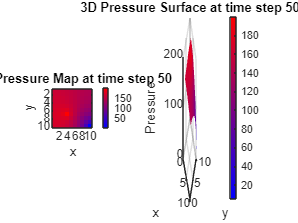

p_bar=p./100000;
[Nx, Ny, Nt] = size(p_bar);

x = 1:Nx;
y = 1:Ny;
[X, Y] = meshgrid(y, x);

% Define the axis of the graphs 
p_min = min(p_bar(:));
p_max = max(p_bar(:));

fig = figure;
cmap = [linspace(0,1,256)', zeros(256,1), linspace(1,0,256)'];

for t = 1:Nt
    % Subplot 1: 2D colormap
    subplot(1,2,1);
    imagesc(x, y, p_bar(:,:,t));
    axis equal tight;
    colormap(cmap);
    %caxis([p_min p_max]); % uncomment if you want to fix the axis
    colorbar;
    title(['2D Pressure Map at time step ', num2str(t)]);
    xlabel('x');
    ylabel('y');
    
    % Subplot 2: 3D surface
    subplot(1,2,2);
    surf(X, Y, p_bar(:,:,t));
    shading interp;
    colormap(cmap);
    %caxis([p_min p_max]); % uncomment if you want to fix the axis
    colorbar;
    title(['3D Pressure Surface at time step ', num2str(t)]);
    xlabel('x');
    ylabel('y');
    zlabel('Pressure');
    %zlim([p_min p_max]);  % % uncomment if you want to fix the axis
    view(45,30);  % angle
    
    drawnow;
    pause(0.1);

end
